% Define the file path (change 'your_file_path' to the actual path of your Excel file)
filename = '~/down/ADC_Rawdata.xlsx';
% Load the data from the Excel file
data = readtable(filename);

% Extract individual variables by converting the table data to arrays using curly braces

% Trial 1
id_psu1 = data{1:31, 2};              % ID measured by power supply
Vid_scope1 = data{1:31, 5};           % voltage from hall effect sensor measured with oscilloscope
Vid_dn1 = data{1:31, 9};              % voltage from hall effect sensor measured with ADC
id_scope1 = (Vid_scope1 - 0.5) / 0.8; % current calculated from Vid
id_dn1 = (Vid_dn1 - 0.5) / 0.8;       % current calculated from Vid_scope

id_dn1_error = (id_psu1 - id_dn1) % total system error, difference between PSU value and ADC value

id_dn1_error =    0.007641250000000
   0.003613750000000
  -0.003540000000000
  -0.013211250000000
  -0.030763750000000
  -0.029407500000000
  -0.027747500000000
  -0.011990000000000
  -0.018766250000000
  -0.034353750000000


id_dn1_error_percent = ((id_psu1 - id_dn1)./(id_psu1)).*100

id_dn1_error_percent =                  Inf
   6.818396226415054
  -3.436893203883470
  -8.634803921568633
 -15.695790816326518
 -11.623517786561234
  -9.157590759075902
  -3.396600566572254
  -4.656637717121570
  -7.583609271523170



% Trial 2
id_psu2 = data{35:65, 2};
Vid_scope2 = data{35:65, 5};
Vid_dn2 = data{35:65, 9};
id_scope2 = (Vid_scope2 - 0.5) / 0.8;
id_dn2 = (Vid_dn2 - 0.5) / 0.8;

% Trial 3
id_psu3 = data{69:99, 2};
Vid_scope3 = data{69:99, 5};
Vid_dn3 = data{69:99, 9};
id_scope3 = (Vid_scope3 - 0.5) / 0.8;
id_dn3 = (Vid_dn3 - 0.5) / 0.8;

% Trial 4
id_psu4 = data{103:133, 2};
Vid_scope4 = data{103:133, 5};
Vid_dn4 = data{103:133, 9};
id_scope4 = (Vid_scope4 - 0.5) / 0.8;
id_dn4 = (Vid_dn4 - 0.5) / 0.8;

% Average of all trials
id_psu_avg = (id_psu1 + id_psu2 + id_psu3 + id_psu4) / 4;
Vid_scope_avg = (Vid_scope1 + Vid_scope2 + Vid_scope3 + Vid_scope4) / 4;
Vid_dn_avg = (Vid_dn1 + Vid_dn2 + Vid_dn3 + Vid_dn4) / 4;
id_scope_avg = (id_scope1 + id_scope2 + id_scope3 + id_scope4) / 4;
id_dn_avg = (id_dn1 + id_dn2 + id_dn3 + id_dn4) / 4;

% Ideal values
id_ideal = id_psu_avg;

% Error calculation, uses averages of all trials
id_hall_err = (id_psu_avg - id_scope_avg); % hall effect error, difference between PSU value and scope value 
id_dn_err = (id_scope_avg - id_dn_avg); % ADC error, difference between scope value and ADC value
id_total_err = (id_psu_avg - id_dn_avg) % total system error, difference between PSU value and ADC value

id_total_err =   -0.005734375000000
  -0.004088437500000
  -0.008565000000000
  -0.019079062500000
  -0.028389687500000
  -0.023337500000000
  -0.025810625000000
  -0.011918125000000
  -0.029455937500000
  -0.033017812500000



id_total_err_percent = ((id_psu_avg - id_dn_avg)./(id_psu_avg)).*100

id_total_err_percent =                 -Inf
  -7.900362318840607
  -8.438423645320185
 -12.677117940199350
 -14.302109571788431
  -9.363089267803403
  -8.589226289517462
  -3.388237384506058
  -7.336472602739705
  -7.321022727272732


% Compensate using two point gain error calculation
y1 = id_dn_avg(3)

y1 =    0.110065000000000


y2 = id_dn_avg(28)

y2 =    2.474603750000000


x1 = id_psu_avg(3)

x1 =    0.101500000000000


x2 = id_psu_avg(28)

x2 =    2.400500000000000



gain_error = (y2 - y1)/(x2 - x1)

gain_error =    1.028507503262288


offset_error = y1 - gain_error * x1

offset_error =    0.005671488418878



% example compensation
uncal_real = id_psu_avg(10)

uncal_real =    0.451000000000000


uncal_measured = id_dn_avg(10)

uncal_measured =    0.484017812500000


cal_value = (uncal_measured - offset_error)/gain_error

cal_value =    0.465087831215496



% try calibrating a trial
id_dn1_cal = (id_dn1 - offset_error)/gain_error

id_dn1_cal =   -0.012943744578092
   0.042503104199498
   0.098072703661549
   0.156090024692977
   0.214964169809017
   0.269065622470767
   0.316065765733380
   0.349359154348813
   0.404561717110790
   0.468331305365581


id_dn1_cal_error = (id_psu1 - id_dn1)

id_dn1_cal_error =    0.007641250000000
   0.003613750000000
  -0.003540000000000
  -0.013211250000000
  -0.030763750000000
  -0.029407500000000
  -0.027747500000000
  -0.011990000000000
  -0.018766250000000
  -0.034353750000000


id_dn1_cal_error_percent = ((id_psu1 - id_dn1_cal)./(id_psu1)).*100

id_dn1_cal_error_percent =                  Inf
  19.805463774532619
   4.783782852864861
  -2.019623982337658
  -9.675596841335031
  -6.350048407417868
  -4.312133905406061
   1.031401034330500
  -0.387522856275312
  -3.384394120437374


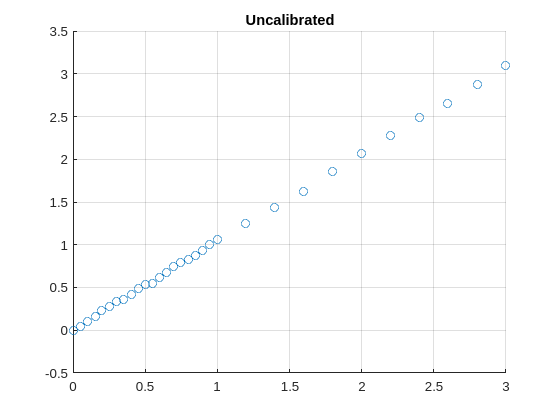


% compare datas 
figure;
scatter(id_psu1, id_dn1); title("Uncalibrated"); grid on;

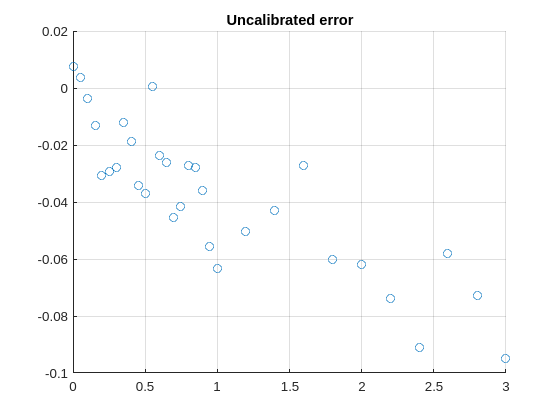

figure;
scatter(id_psu1, id_dn1_error); title("Uncalibrated error"); grid on;

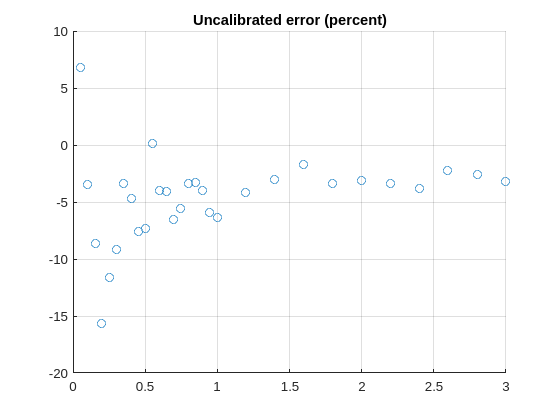

figure;
scatter(id_psu1, id_dn1_error_percent); title("Uncalibrated error (percent)"); grid on;

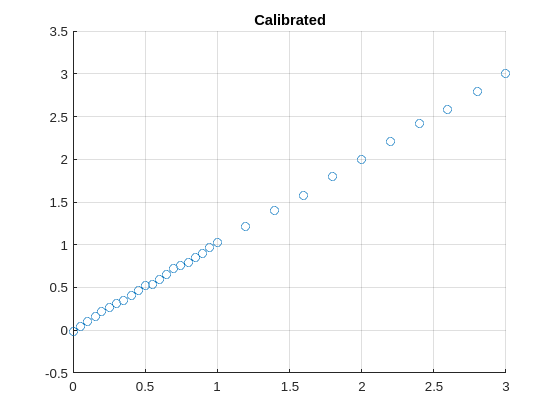


figure;
scatter(id_psu1, id_dn1_cal); title("Calibrated"); grid on;

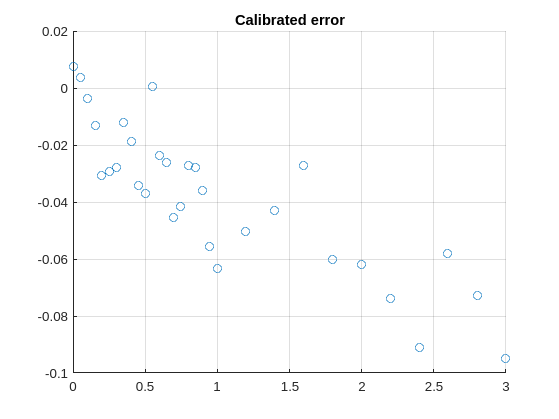

figure;
scatter(id_psu1, id_dn1_cal_error); title("Calibrated error"); grid on;

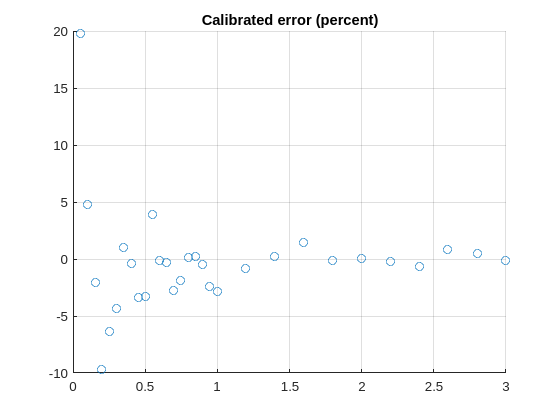

figure;
scatter(id_psu1, id_dn1_cal_error_percent); title("Calibrated error (percent)"); grid on;